%Requirment 9
%Euler Step to Solve ODE
chargeTimehr=11;

Vmax=3.7;
chargeRate=[.1, .2, .5, 1, 1.5, 2];
ESR=0.1;
dt=0.5;
U=3600/dt;
t=0:dt:3600*chargeTimehr;
I=zeros(length(t),length(chargeRate));
V=zeros(length(t),length(chargeRate));
x=zeros(length(t),length(chargeRate));
x2=zeros(length(t),length(chargeRate));
x3=zeros(length(t),length(chargeRate));

    R1=0.01;
    R2=0.01;
    C1=600;
    C2=10;
    
for j=1:length(chargeRate)
    Imax=chargeRate(j);
    V(1,j)=2.6;
    I(1,j)=Imax;
    x(1,j)=0;
  
    for i=2:length(t)
        I(i,j)=cccvRC(x(i-1,j),x2(i-1,j),x3(i-1,j),Imax,Vmax);
        x(i,j)=x(i-1,j)+(I(i,j)/U);
        x2(i)=I(i-1,j)*dt+x2(i,j)*dt/(R1*C1);
        x3(i)=I(i-1,j)*dt+x3(i,j)*dt/(R2*C2);
        V(i,j)=(2.6+2.35*x(i,j)-3.75*x(i,j)^2+2.5*x(i,j)^3)+ESR*I(i,j)+x2(i)/C1+x3(i)/C2;
    end

end

t2=t/3600;
fig2=figure('Position', [100, 100, 1024, 1200]);

subplot(4,1,2);
h1=plot(t2,V);
title("Charge Voltage Through CCCV Charging")
%xlabel("Time (s)")
ylabel("Voltage (V)")
grid on
hold on

subplot(4,1,3);
h2=plot(t2,I);
title("Charge Current Through CCCV Charging")
%xlabel("Time (s)")
ylabel("Current (A)")
grid on

subplot(4,1,4);
h3=plot(t2,x);
title("Charge State Through CCCV Charging")
xlabel("Time (Hr)")
ylabel("Charge State (Ah)")
grid on
hold off

hL = subplot(4,1,1);
poshL = get(hL,'position');     % Getting its position

lgd = legend(hL,[h1;h2;h3],'Imax=0.1','Imax=0.2','Imax=0.5','Imax=1','Imax=1.5','Imax=2');

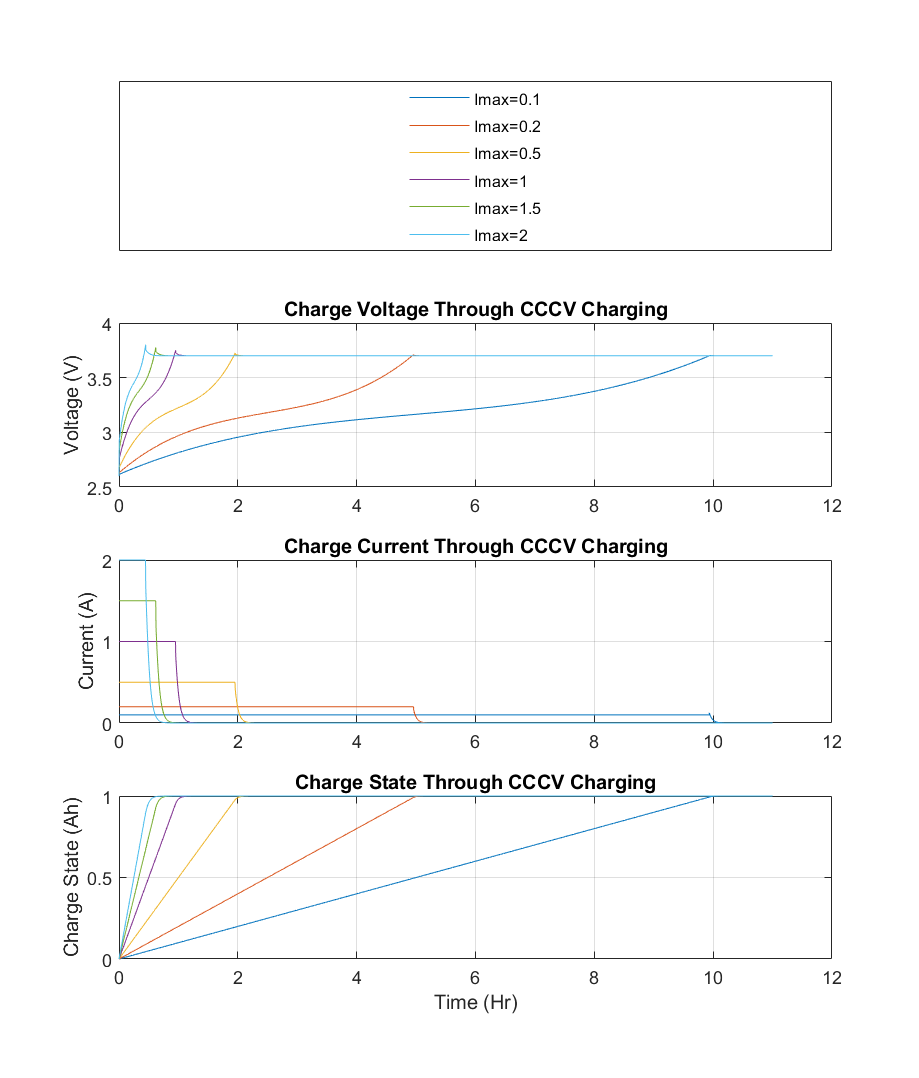

set(lgd,'position',poshL);      % Adjusting legend's position
axis(hL,'off');  